# Replicating, evaluating and extending Stock and Watson 2010

This tutorial illustrates the typical steps to take in replicating the empirical analyses of a time series based paper. It serves as a guide to what is expected in your research project. You may use the code provided here, but you should format your results into a proper report. This tutorial is a story-telling walk through of the methods, not a report. 

Paper under investigation (referred to as SW below): 

Stock, J.H. and Watson, M.W., 2001. Vector autoregressions. *Journal of Economic perspectives*, *15*(4), pp.101-115.

## Step 1: Obtain data

SW use three quarterly series:

- Inflation rate $\pi_t=400ln\frac{P_t}{P_{t-1}}$,  constructed from the US GDP deflator $P_t$. We will instead employ the CPI to see if this has a material impact. 

- Unemployment rate $u_t$

- Interest rate, specifically, the federal funds rate $R_t$

Their sample is 1960Q1 to 2000Q4. We will get the longest sample we can to evaluate whether the results they show are stable over time. 

I used the FRED ([https://fredaccount.stlouisfed.org/](https://fredaccount.stlouisfed.org/)) database, where you can select the frequency of choice. Although I will show you how to construct quarterly data from monthly using Matlab functions as part of the illustration. 

I created a .mat file with the data in monthly frequency called `StockWatson_data.mat`. 

clear
load('StockWatson_data.mat')

## Step 2: Perform necessary data transformations

Matlab has nice control over the display of date-time objects:

Date
Date = datetime(Date,'InputFormat','dd-MMMM-yyyy','Format','MMMM yyyy')

Compute inflation from the CPI series

inflation_CPI = [nan; 400 * log(CPI(2:end)./CPI(1:end-1))] 
% note that we add a nan at the top of the column so that it remains the
% same length as all the others

In matlab, many convenient operations are only available if the data are in `timetable` format

data_m = timetable(Date,inflation_CPI,unemployment,interest)

Convert to quarterly data by averaging

- NOTE: averaging is *not* always the correct way to aggregate. 

My rule is: 

- Average Prices

- Accumulate Flows

- Use the final value of Stocks

% aggregate to quarterly data:
data_q = retime(data_m,'quarterly','mean');
% reformat the date:
data_q.Date = datetime(data_q.Date,'InputFormat','MMMM yyyy','Format','yyyyQQQ')

## Step 3: Visualize data and compare to figures in original

In this case, SW do not provide the figures, but I would always check them. If the paper you replicate provides figures, show yours next to theirs, one-for-one and discuss any obvious differences.

variable_names = data_q.Properties.VariableNames;

plot(data_q.Date,data_q{:,1:end})
legend(variable_names)

Note that the inflation series behaves differently from the other two.The inflation series is seems far more stationary than the other two series. 

Did SW make a mistake? Or did we compute it wrong? 

We followed exactly what they stated in the paper. This is always the first step. 

Later, one can check what impact changes would have.

## Step 4: Assess the properties of the data 

In a full replication exercise (like your research project), one would check the properties of the data and evaluate whether they conform to the proposed data generating process in the paper, and whether they satisfy the requirements for the empirical methods used. 

SW skip this step as this is a short article to highlight  the uses of VARs with as little clutter as possible. Deep, novel empirical studies should always be dilligent in this regard. 

Whether or not the paper you replicate reports such analyses, you should do so in your research project. At the very least, unit root tests, which you should condense and report on briefly. If the replicated paper reports results, compare them one-to-one. 

We will skip this step as we covered them in previous tutorials.

In this example, one would almost certainly find that most tests will not reject the null of a unit root in the unemployment and interest rate series. 

Are they then to be treated as I(1)? 

No. One must always use economic reasoning along with statistical tests. I(1) variables have unbounded range, while series like unemployment are bounded, hence cannot be I(1). The issue is nuanced, however. More later. 

## Step 5: Replicate the empirical results of the paper

Critically: The first step is always to do *exactly* what the authors report doing, regardless of your findings in the step above. Whether or not you agree with the decisions made in the paper, the first thing to check whether their results are reliable. Put differently, do we get the same results if we do exactly what they say they did? 

If this fails, one starts looking for reasons to discuss in the report. If one cannot find exactly the same data, one would expect small differences. 

### Select the sample:

SW use a sample from 1960Q1 to 2000Q4.

The convenient format control of matlab dates makes this very simple to do in a human readable way: 

% create indicator variable that is true in the sample and false otherwise
sample_SW = (data_q.Date >= '1960Q1') & (data_q.Date <= '2000Q4')

% plot again to confirm accurate sample and to focus on the in sample
% behaviour of the series

plot(data_q.Date(sample_SW), data_q{sample_SW,:} ) 
% note: arrays are indexed with (), timetables are indexed using {}
legend(variable_names)

### Set up the VAR model:

SW reports estimating a VAR(4), so we do the same.

n_var = 3; % number of variables
n_lag = 4; % number of lags
model_SW = varm(n_var,n_lag);
model_SW.SeriesNames = variable_names;

### Estimate the model

Note how simple it would be to change the sample used in the estimation. You would just have to create a new indicator variable for the sample of your choice, or use the whole sample. The estimate command, however, cannot take timetables as input, so you have to add indexing to the timetable to extract the data array achieve that. 

[estimate_SW, std_errors_SW,logL_SW,residuals_SW] = ...
    estimate(model_SW,data_q{sample_SW,:}) % use data_q{:,:} to use the full available sample

summarize(estimate_SW)

#### Compute and compare the impulse response functions

The key thing we want to know is how close our results are to theirs, the main result I am aiming for in this illustration is Figure 1, the impulse responses from a recursive identification scheme ordered $\pi_t,u_t,R_t$. 

This means:

- the inflation rate does not contemporaneously respont to shocks in unemployment or interest rates, 

- the unemployment rate responds contemporaneously only to inflation, and 

- the interest rate responds contemporaneously to both other variables.

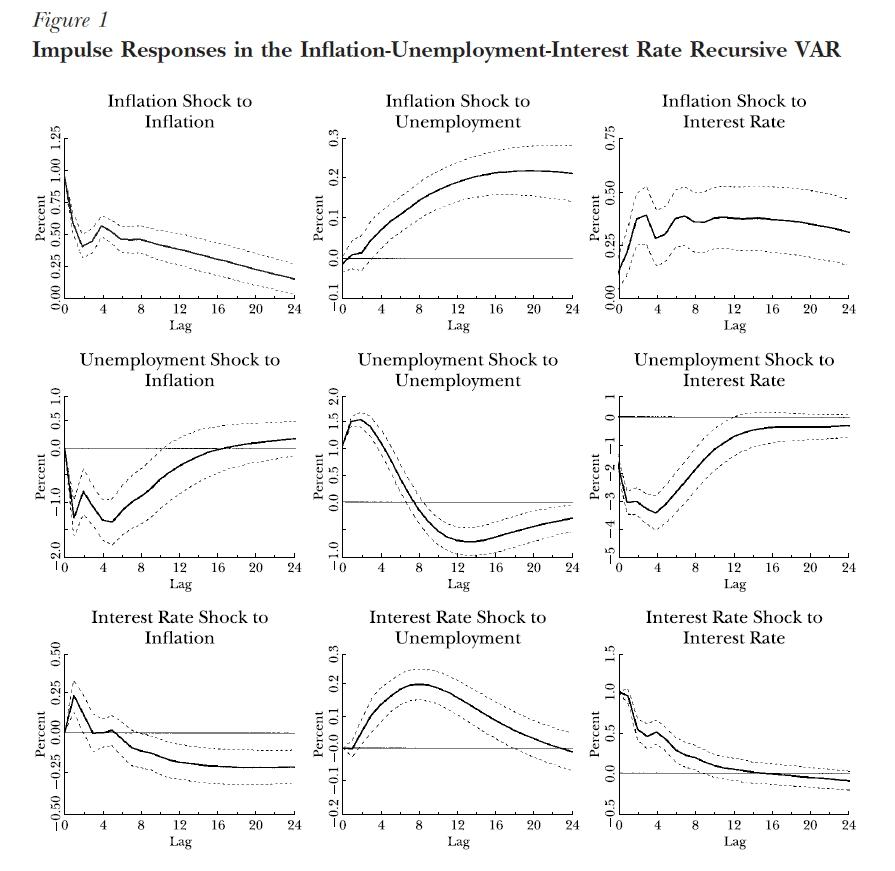

With an estimated VAR stored as above, the command `irf` constructs the impulse response functions. It's default is a recursive ordering based on the order in which the data series are entered. The data matrix was constructed with this in mind. Inflation in the first column, unemployment in the second and interest rate in the third.

It also constructs the lower and upper confidence bounds. By default it simulates the model 100 times, but there are other options you can explore. 

[irf_SW,irf_lower_SW,irf_upper_SW] = irf(estimate_SW,'NumObs',24);

I wrote a function `irf_plot `that graphs IRFs based on the structure of the output. It is not yet fully professional, but can do enough for our purposes

% set the options for the IRF plotter
short_names = {'Infl','Unem','Intr'};

options.shock_names = short_names;
options.variable_names = short_names;
options.confidence_bands = false;

% call the plotting function
irf_plot(irf_SW,irf_lower_SW,irf_upper_SW,options) 

We get quite close to the published figure. Most of the shapes of the IRF figures are very similar to those in SW. 

One thing to note is that the matlab irf function assumes an impulse of one standard deviation, where as the shock studied in SW is a unit size (i.e. shocking inflation by 1 percentage point). 

It would be a good test of understanding for you to figure out how to convert the impulse response to a 1 standard deviation shock to a 1 unit shock. 

Next, we add the confidence intervals

options.confidence_bands = true;
irf_plot(irf_SW,irf_lower_SW,irf_upper_SW,options)

They seem a bit wider than those of SW. Are our estimates uncertain? No.

Note that SW uses a 66% confidence interval rather than a 95% confidence interval, so we have to reestimate the irfs to get a different confidence band.

[irf_SW,irf_lower_SW,irf_upper_SW] = irf(estimate_SW,'Confidence',0.66,'NumObs',24);

irf_plot(irf_SW,irf_lower_SW,irf_upper_SW,options)

Some fo the confidence bounds are assymetric! what is happening? 

SW constructed their confidence bands by computing the standard deviation and then adding and subtracting it from the IRF directly.

The matlab irf function constructs the confidence bounds by simulation the model 100 times and then using that to construct the quantiles of the distribution. The simulation approach is more general as it allows for assymetric distributions. The function allows a variety of options that you can explore as you advance in time series econometrics. 

#### Replicate their specification test

SW presents only a set of Granger causality tests. 

gc_SW = gctest(estimate_SW)

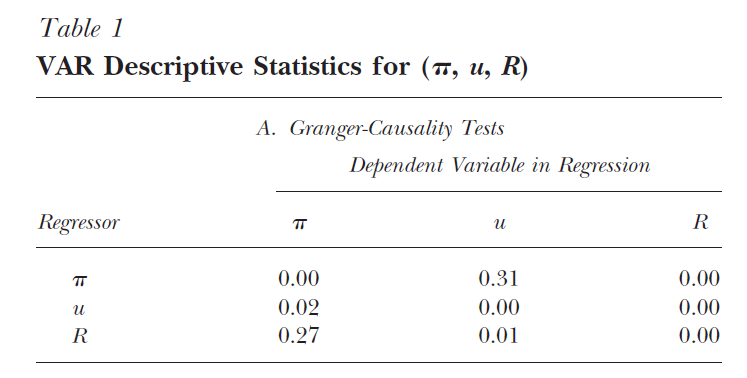

The SW table provides p-values for the tests, and is read as follows: the columns are the equations for each of the variables, the rows are the variables excluded from the regression. 

The null hypothesis is that the row variable does not Granger cause the column variable.

For instance, we cannot reject the hypothesis that inflation $\pi_t$ does not Granger cause unemployment $u_t$ as the p-value of that test is 0.31. That means that the equation for unemployment is not statistically significantly affected when inflation is excluded from it. 

For your report,  I would reformat either the SW results to more clearly compare to your own. One of the things that will make me like your report is if it is convenient for me to read...

#### Compute and compare variance decompostions:  

The matlab command is `fevd` which stands for forecast error variance decomposition.

SW presents this in a table for horizons of 1, 4, 8, and 12 quarters, so it makes sense to do so ourselves.

By default matlab computes the first 20 periods, so we just have to select the rows of interest to us.

A good coding exercise will be to find a way to represent these graphically. 

fevd_SW = fevd(estimate_SW)
%

The output `fevd_SW` is an 3D array, with dimensions sizes: `horizons` x `shocks` x `variables.`

The rows of the FEVD are the different horizons, the FEVD of inflation is stored in the first page: `fevd_SW(:,:,1), `and the contribution of inflation to the forecast variance of inflation over time is stored in the first column of the first page, `fevd_SW(:,1,1)`.

% SW forecast horizons:
forecast_horizons = [1;4;8;12];

% display the fevd for inflation
table(forecast_horizons, round( fevd_SW(forecast_horizons,:,1)*100, 0))
% another coding exercise would be to make this table neater.

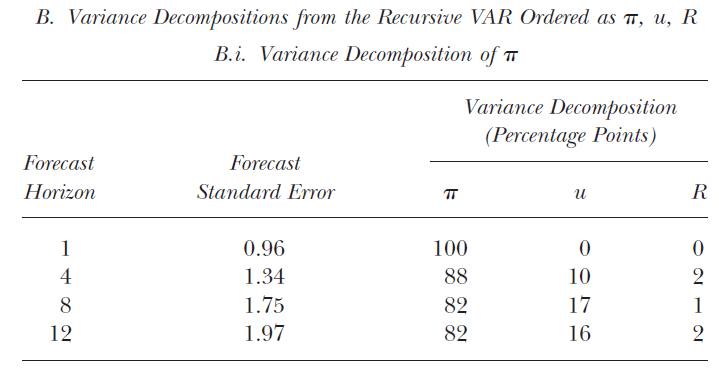

Here our results look a little different, although not materially - the story told is still the same. One reason might be data revisions.

I leave the rest of the FEVDs for you to complete. In your research project, you will attempt to replicate all the published results (within reason, of the sections you choose to replicate).

## Step 6: assess the quality of the model

Now that we know we get almost exactly the same results as those in the paper when we follow their steps, we go further and investigate whether the model satisfies the theoretical requirements we discussed. 

We will conduct several specification tests to check whether the model that produces the results is a valid representation of the underlying data generating process. 

If the paper you replicate does give specification test results, replicate them and then see whether there are more that you can think of that they did not provide (e.g. alternative unit root tests etc). 

We will consider three aspects:

### Congruency

#### Stationarity of the VAR

Note that the standard output already gives the answer to the question whether the system is stationary:

estimate_SW.Description

However, it does not report directly how close the characteristic roots are to unity. 

I wrote a function that does this for any VAR/VECM model estimated as above. It takes the AR coefficients as stored in the estimation results as input, as well as optional specifications. 

% set options and call the roots test

options.report = "figure"; 
VAR_roots_test(estimate_SW.AR,options);

options.report = "table";
VAR_roots_test(estimate_SW.AR,options)

While all the characteristic roots are in the unit circle, two are quite large and might raise concerns about non-stationarity. In this case, it is the result of the very persistent variables - unemployment and to a lesser extent, interest rates. 

#### White noise errors

Evaluate the characteristics of the residuals.

Again, I wrote a simple function that does two things: it plots the residuals (standardized or not) to inspect for outliers, and conducts Ljung-Box tests for residual autocorrelation. This code is still incomplete, but works. You can change the hard coded components to practice your coding.

options.standardize = true;
options.names = variable_names;
options.outlier_def = 4; % number of standard deviations considered an outlier

VAR_residual_evaluation(residuals_SW, options)

There are no worrying autocorrelations, so there is no evidence in these tests of a potential problem with congruency. In a complete report, you should consider testing the square of the residuals for autocorrelation (which would imply heterosckedasticity) and normality (which will determine how accurate statistical tests based on an assumption of normal errors are).

### Parsimony

We already did Granger causality above, and found some negative results.

#### Lag exclusion tests

SW deliberately side-step the issue of lag-length selection to focus on other aspects. We investigate a bit deeper.

To test whether we can exclude the 4th lag from the model above, we conduct a likelihood ratio test (similar to an F test, but motivated in a Maximum Likelihood context with normal errors)

We estimate a new model with only 3 lags. This is a restriction on the VAR(4) that SW use. 

The likelihood ratio test provides evidence whether the drop in fit from the restriction is statistically significant. The degrees of freedom of the test is the difference in the number of coefficients estimated, which is easy to obtain from `estimate` output.

% Set up a VAR(3)
model_VAR3 = varm(n_var,3);
model_VAR3.SeriesNames = variable_names;
% Estimate the VAR(3)
[estimate_VAR3, std_errors_VAR3,logL_VAR3,residuals_VAR3] = ...
    estimate(model_VAR3,data_q{sample_SW,:});

% obtain the results from both the VAR(4) of SW and the VAR(3)
results_SW = summarize(estimate_SW)
results_VAR3 = summarize(estimate_VAR3)

num_est_SW = results_SW.NumEstimatedParameters;
num_est_VAR3 = results_VAR3.NumEstimatedParameters;

% perform the likelihood ratio test.
% first argument: the log likelihood of the unrestricted model 
% second argument: the log likelihood of the restricted model
% third argument: the degree of freedom - difference in number of estimated
% coefficients. 
[h,pValue,stat,cValue]=lratiotest(logL_SW,logL_VAR3,num_est_SW-num_est_VAR3)

We reject the hypothesis that the true coefficients on the 4th lag are jointly statistically insignificant. A VAR(3) is thus rejected by the data as insufficient to capture the time series properties of this system according to *this *test. 

Another thing to check is whether the VAR(4) itself is large enough, or equivalently, to test whether a VAR(5) can be validly reduced to a VAR(4) without losing significant fit. 

% Set up and estimate a VAR(5)
model_VAR5 = varm(n_var,5);
model_VAR5.SeriesNames = variable_names;
[estimate_VAR5, std_errors_VAR5,logL_VAR5,residuals_VAR5] = ...
    estimate(model_VAR5,data_q{sample_SW,:});

% Store the results
results_VAR5 = summarize(estimate_VAR5)
num_est_VAR5 = results_VAR5.NumEstimatedParameters;

% Perform the test
[h,pValue,stat,cValue]=lratiotest(logL_VAR5, logL_SW,num_est_VAR5-num_est_SW)

% notice that i used the same variable names as the previous test? this is
% very bad coding practice and can lead to mistakes! avoid!

Similar to the result above this test result suggests that the VAR(4) is not a valid reduction of the VAR(5). 

However, we should never just consider one piece of evidence or ignore the context.

#### Information criteria

What do the information criteria say?

table([results_VAR3.AIC;results_SW.AIC;results_VAR5.AIC],[results_VAR3.BIC;results_SW.BIC;results_VAR5.BIC],'VariableNames',{'AIC','BIC'},'RowNames',{'VAR(3)','VAR(4) SW','VAR(5)'})

Note the conflicting evidence: The AIC selects the VAR(5), the BIC selects the VAR(3), the likelihood ratio tests suggest the VAR(5). In a complete robustness test, you would evaluate a few more lag length choices, say up to 8. 

What would you do if this was preliminary results in your research? There is no simple answer here. One must present the best argument for the preferred model, while being honest about its potential shortcomings. In a larger study, one would use several more types of comparison, such as relative forecasting performance. 

## Conclusion

This tutorial highlighed the typical steps in doing a stationary VAR analysis as well as the main aspects of how to critically replicate an empirical paper. 

In your research project, you will use similar methods, but present them in a formal report that is convenient to read and well organized. 

## Exercise for submission

In your research project, I will also ask you to try some more robustness tests, such as:

- different variables (CPI instead of GDP deflator)

- different transformations (where this is relevant)

- different samples

For the next exercise for submission, I would like you to repeat the steps above for a different part of the sample: you can extend the sample, or choose a subsample of your choice and document whether/how the results change. 

You need not do everthing, but at least compare the impulse response functions and one or two specification tests.  I would suggest you try all the steps, as this will prove valuable exercise to internalize concepts. 